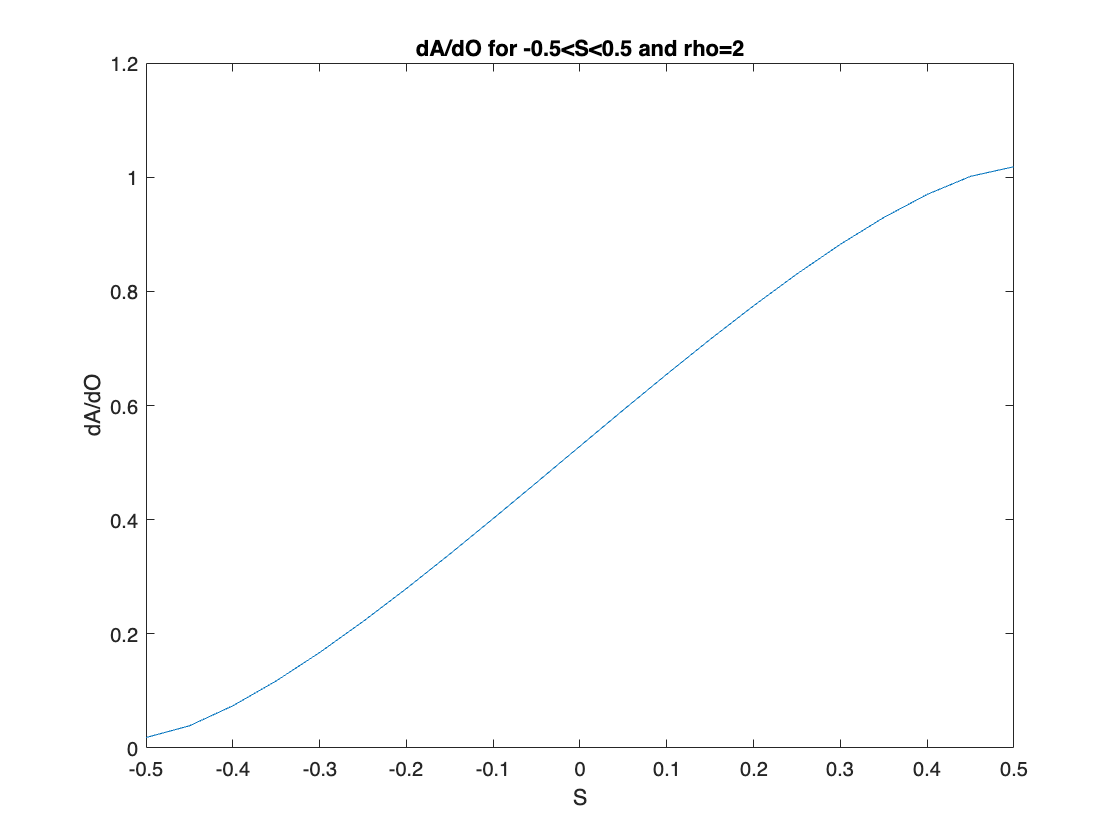

clear
clc
S=-.5:0.05:.5;
rho=2;

S2=-sqrt(rho^2 +S.^2 -1)/rho;
S1 = S*2;
Area=2-(1/pi)*(acos(S1)-S1.*sqrt(1-S1.^2)+acos(S2)-S2.*sqrt(1-S2.^2));
figure;
plot(S,Area)
title('dA/dO for -0.5<S<0.5 and rho=2')
xlabel('S')
ylabel('dA/dO')

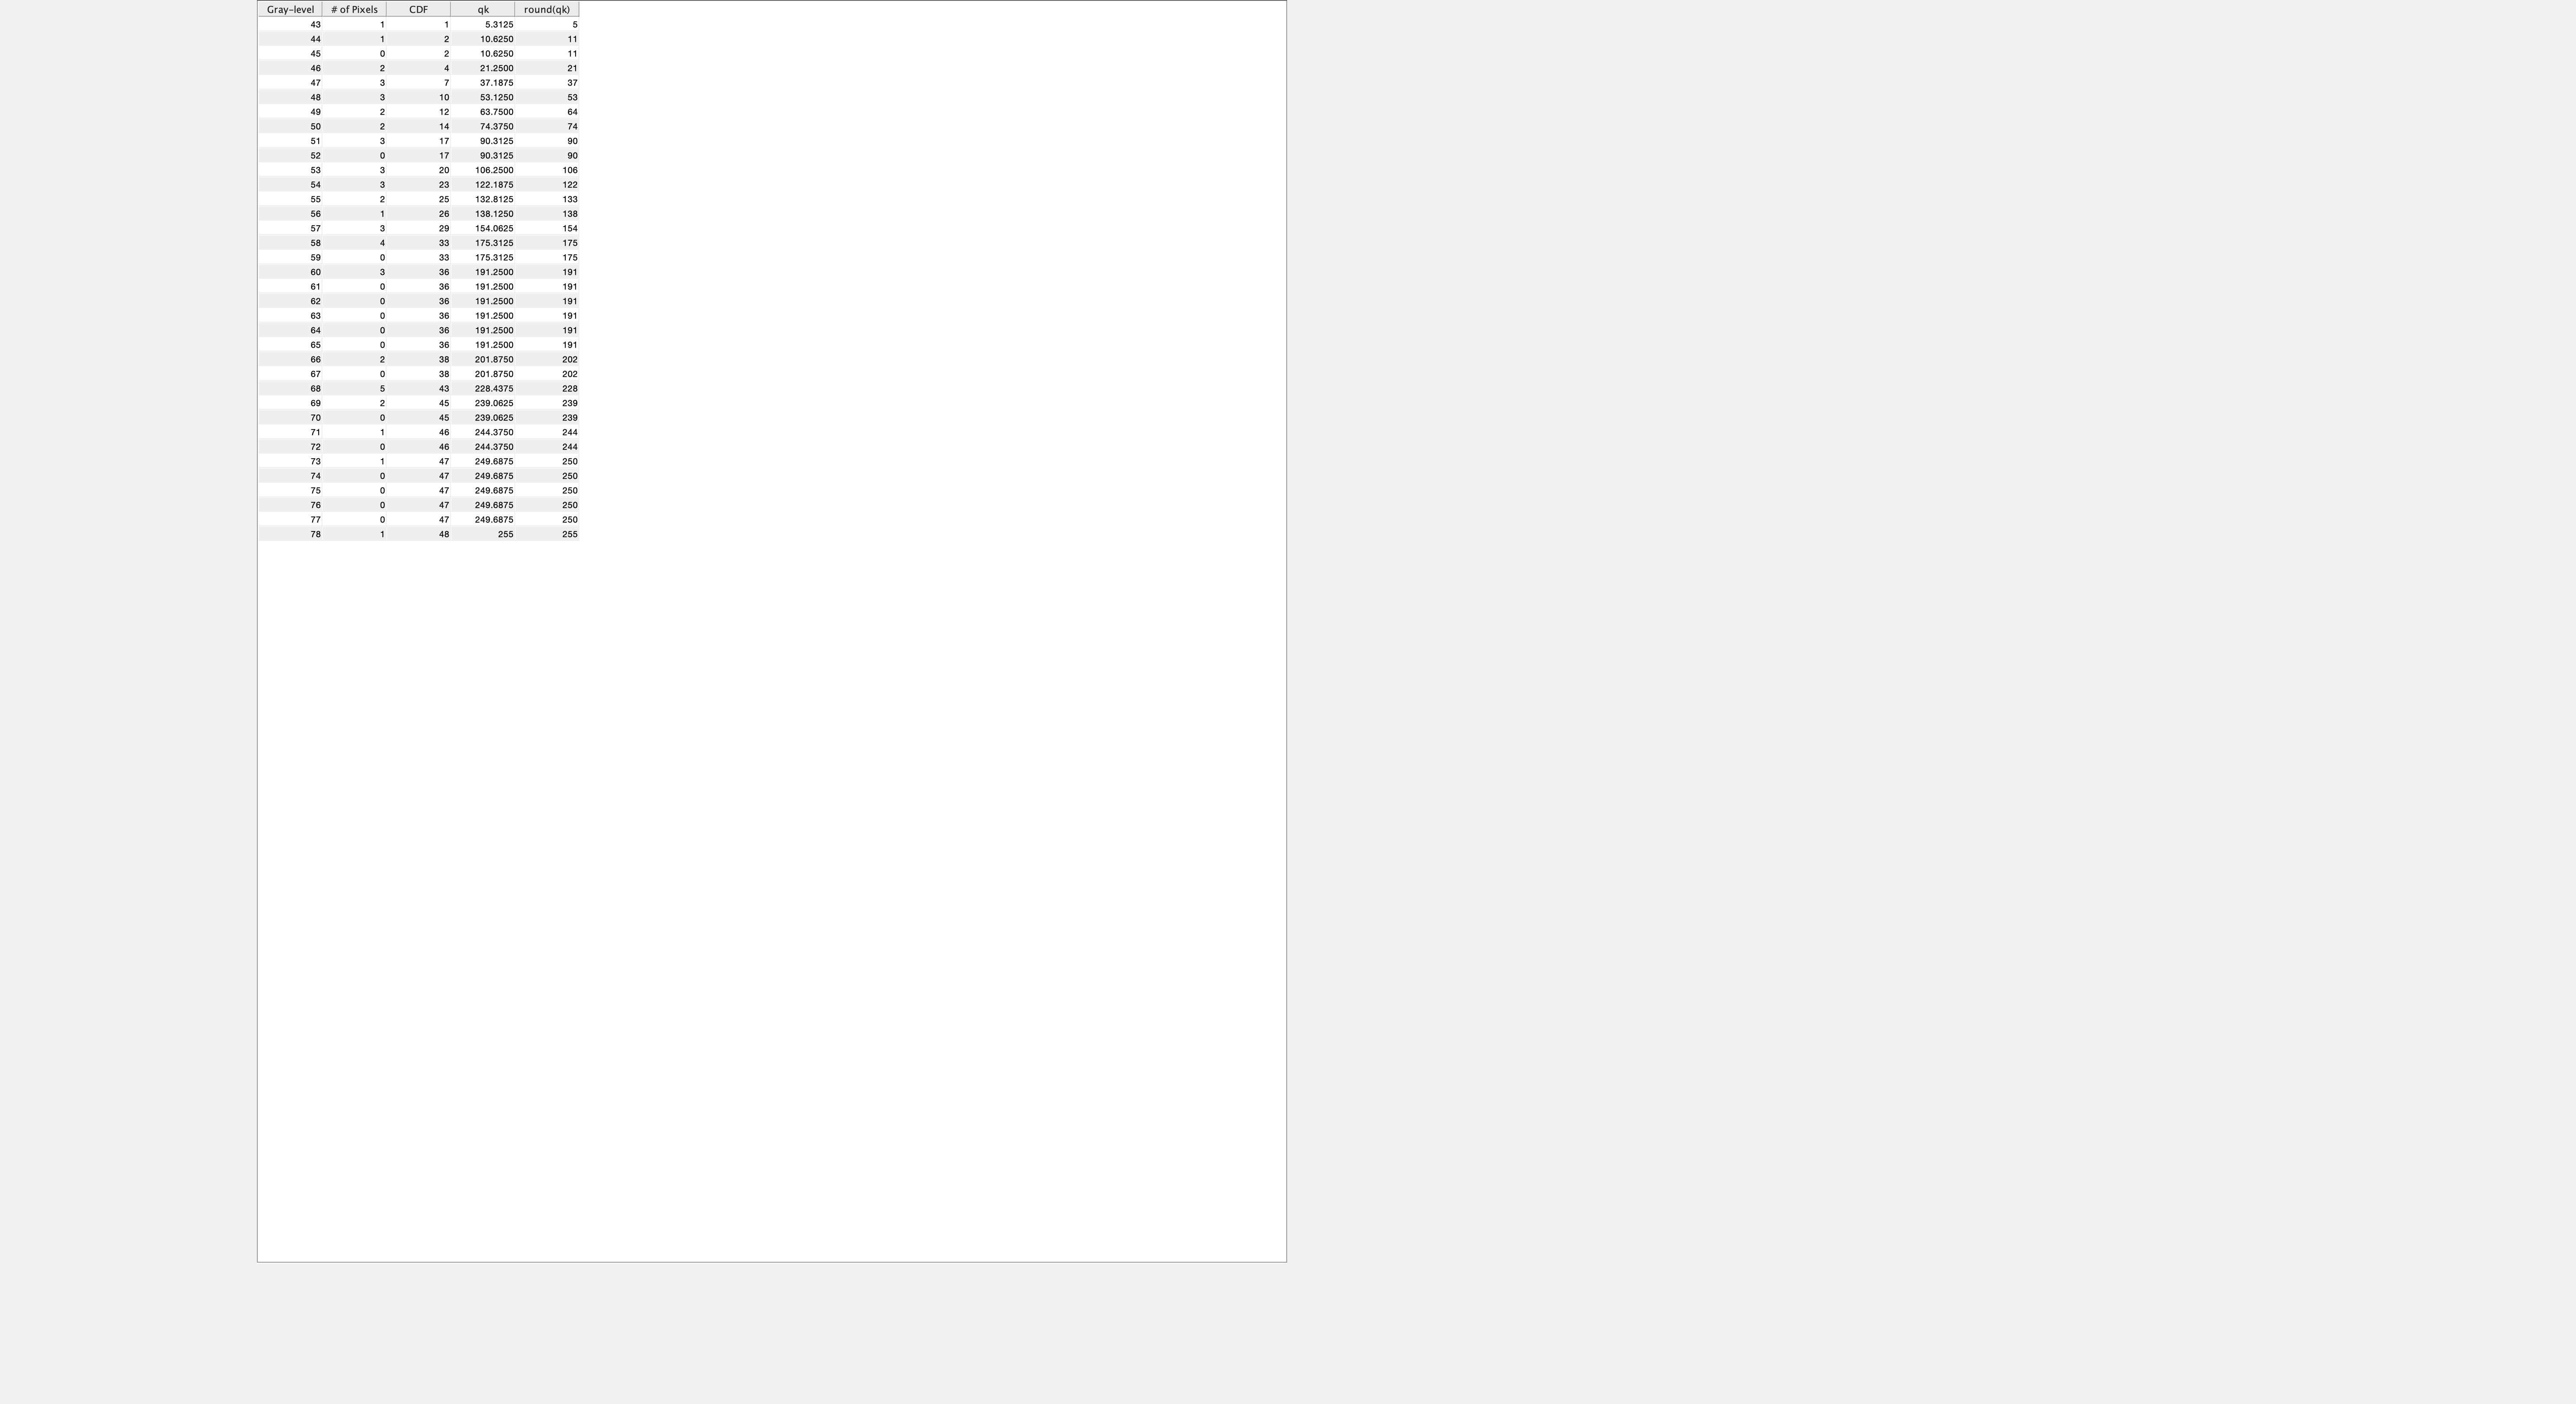


GIm = readmatrix("sub_region_matrix.xlsx");
numofpixels=size(GIm,1)*size(GIm,2);

HIm=uint8(zeros(size(GIm,1),size(GIm,2)));

freq=zeros(79,1);
probf=zeros(36,1);
probc=zeros(36,1);
cum=zeros(36,1);
output=zeros(36,1);
q=zeros(36,1);
rq=zeros(37,1);


for i=1:size(GIm,1)
    for j=1:size(GIm,2)
        value=GIm(i,j);
        freq(value+1)=freq(value+1)+1;
        probf(value+1)=freq(value+1)/numofpixels;
    end
end


sum=0;
no_bins=255;

for i=1:size(probf)
   sum=sum+freq(i);
   cum(i)=sum;
   q(i)=((2^8 -1)/48)*cum(i);
   probc(i)=cum(i)/numofpixels;
   rq(i)=round(q(i));
   output(i)=round(probc(i)*no_bins);

end

for i=1:size(GIm,1)

    for j=1:size(GIm,2)

            HIm(i,j)=output(GIm(i,j)+1);

    end

end

figure('Position',get(0,'screensize'));
dat=cell(36,5);

for i=1:36
dat(i,:)={i+42,freq(i+43),probc(i+43)*48,q(i+43),rq(i+43)};   
end


columnname =   {'Gray-level', '# of Pixels','CDF','qk','round(qk)'};
columnformat = {'numeric', 'numeric', 'numeric', 'numeric','numeric'};
columneditable =  [false false false false false];

t = uitable('Units','normalized','Position',[0.1 0.1 0.4 0.9],'Data', dat,'ColumnName', columnname,'ColumnFormat', columnformat,'ColumnEditable', columneditable,'RowName',[]); 

GIm

GIm =     66    66    60    53    50    50    51    55
    68    68    60    53    48    49    53    57
    69    68    60    51    46    48    54    58
    71    68    58    48    44    47    54    58
    73    68    57    47    43    47    55    58
    78    69    57    49    46    51    54    56


   

HIm

HIm = 6×8 uint8 matrix
   202   202   191   106    74    74    90   133
   228   228   191   106    53    64   106   154
   239   228   191    90    21    53   122   175
   244   228   175    53    11    37   122   175
   250   228   154    37     5    37   133   175
   255   239   154    64    21    90   122   138


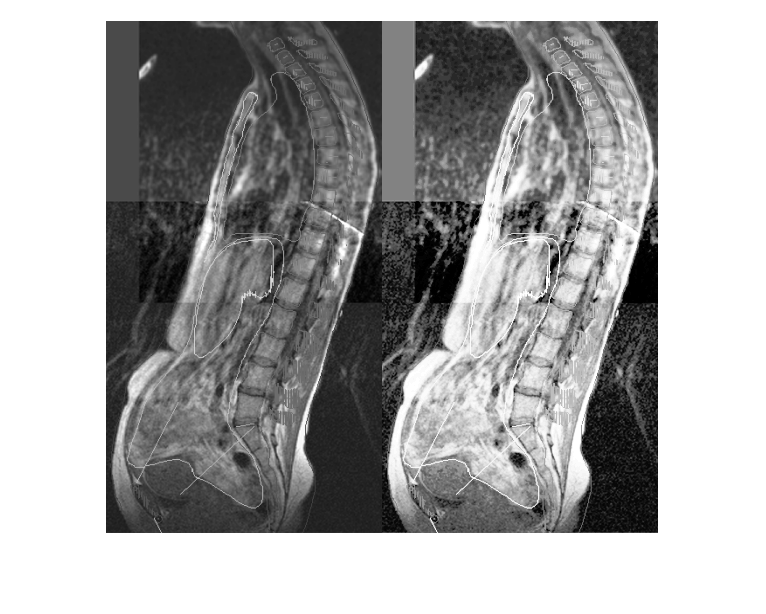


figure;
I = imread('Posture_MRI.png');
J =histeq(I);

imshowpair(I,J,'montage')

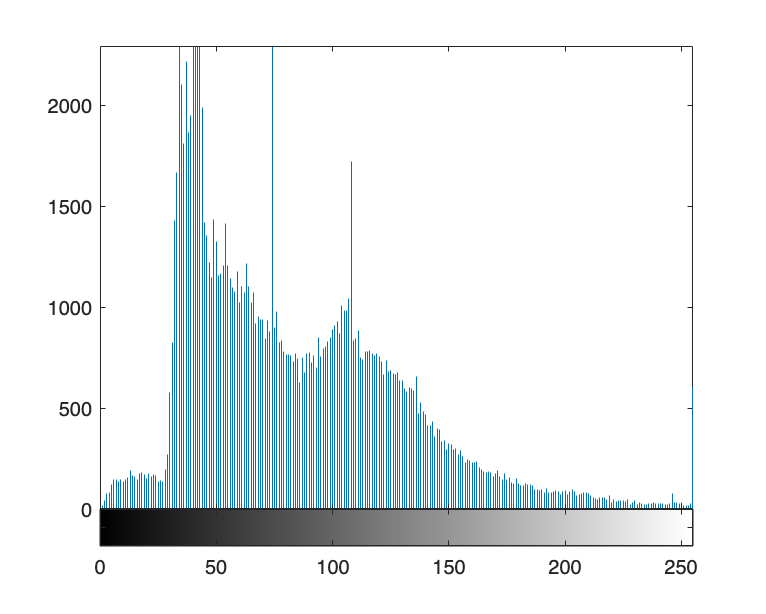


imhist(I)

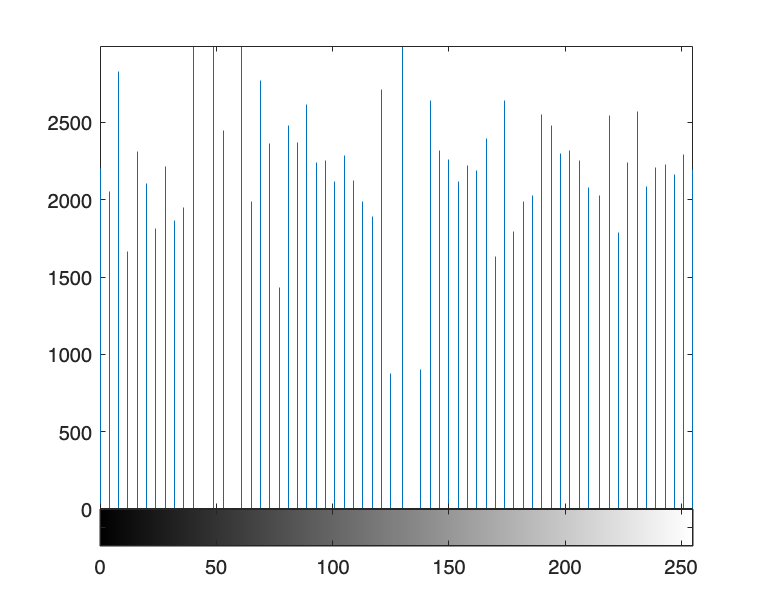


imhist(J)

Sobel_x = [-1 0 1; -2 0 2; -1 0 1];
Sobel_y = [-1 -2 -1; 0 0 0; 1 2 1];

region = [53 48 49; 51 46 48; 48 44 47];

Gx = conv2(region, Sobel_x, 'same');
Gy = conv2(region, Sobel_y, 'same');

gradient_direction = atan2d(Gy(2,2), Gx(2,2))

gradient_direction = 53.7462

gradient_magnitude = sqrt(Gx(2,2)^2 + Gy(2,2)^2)

gradient_magnitude = 18.6011

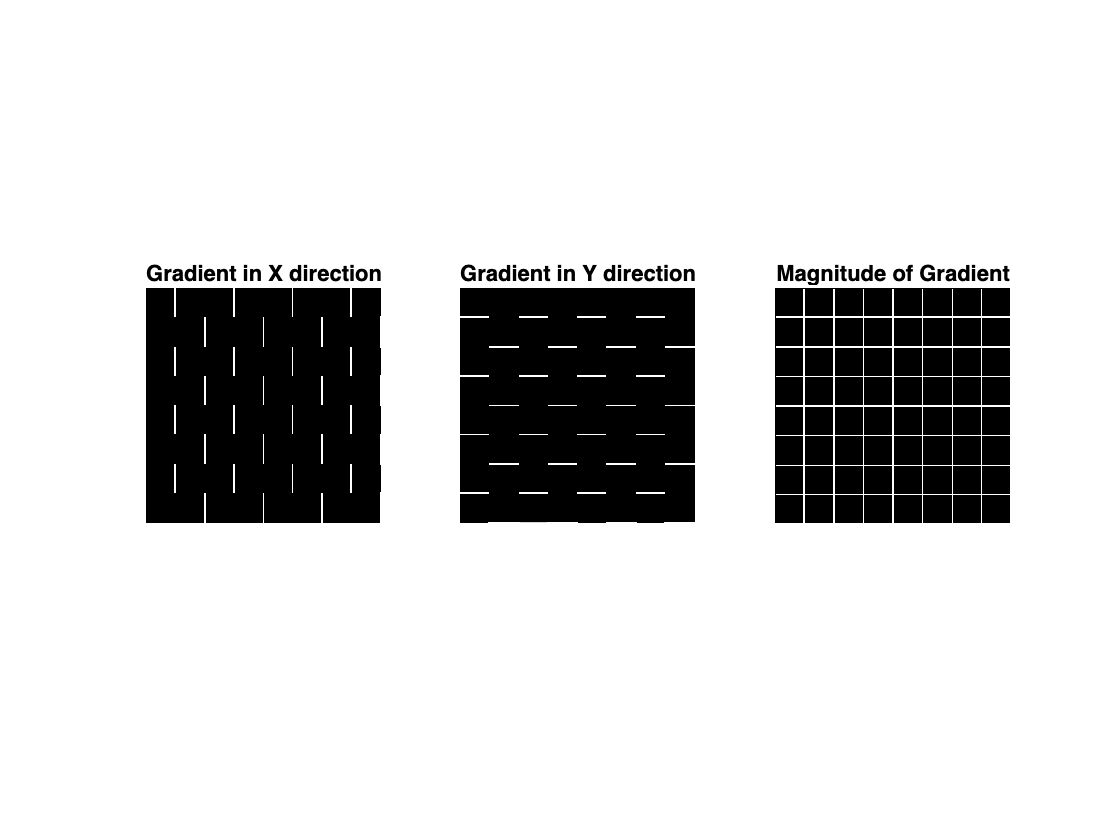

Im = imread('checker.png');

Hx = [-1 0 1; -2 0 2; -1 0 1];
Hy = [-1 -2 -1; 0 0 0; 1 2 1];
Gx = conv2(Im, Hx, 'same');


Gy = conv2(Im, Hy, 'same');

for x=2:length(Im)-2
    for y=2:length(Im)-2
        G(x,y) = sqrt(Gx(x,y)^2 + Gy(x,y)^2);
    end
end

figure;

subplot(1, 3, 1);
imshow(uint8(Gx), []);
title('Gradient in X direction');

subplot(1, 3, 2);
imshow(uint8(Gy), []);
title('Gradient in Y direction');

subplot(1, 3, 3);
imshow(uint8(G), []);
title('Magnitude of Gradient');

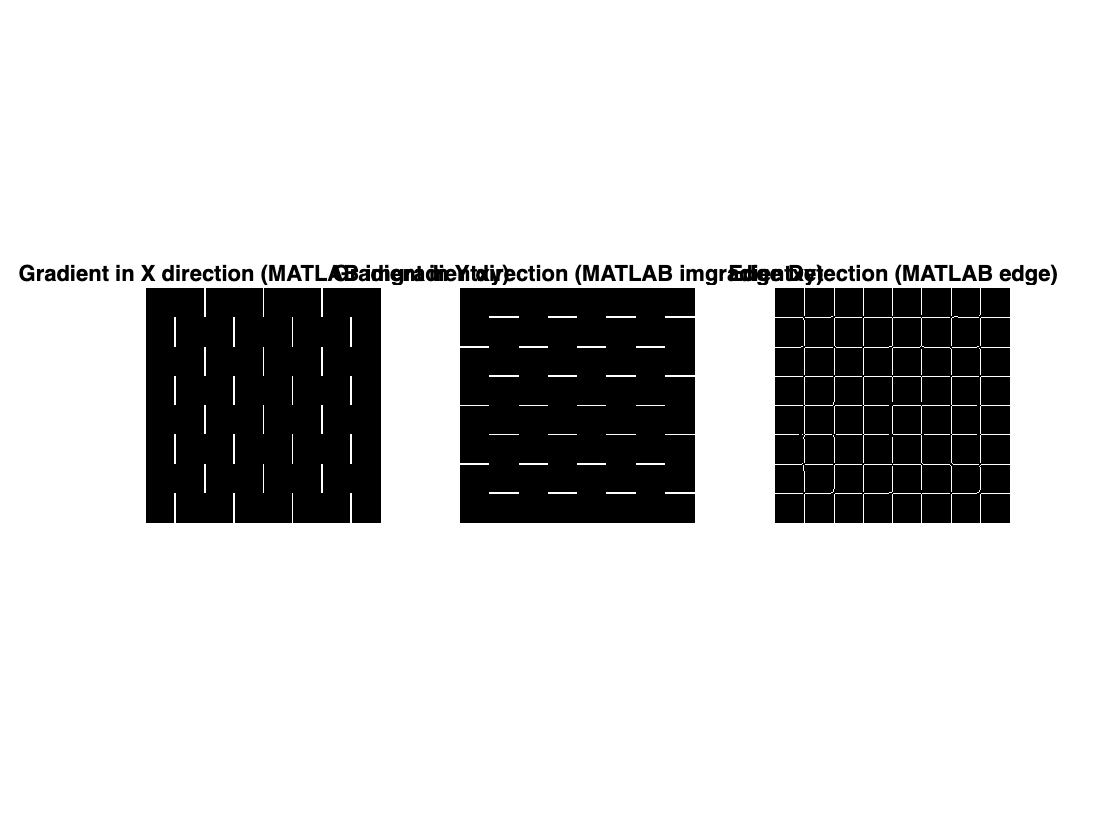



[E, T] = edge(Im, 'sobel');
[Gx_MATLAB, Gy_MATLAB] = imgradientxy(Im);
[mag, f] = imgradient(Im);

figure;

subplot(1, 3, 3);
imshow(E);
title('Edge Detection (MATLAB edge)');

subplot(1, 3, 1);
imshow(uint8(Gx_MATLAB), []);
title('Gradient in X direction (MATLAB imgradientxy)');

subplot(1, 3, 2);
imshow(uint8(Gy_MATLAB), []);
title('Gradient in Y direction (MATLAB imgradientxy)');

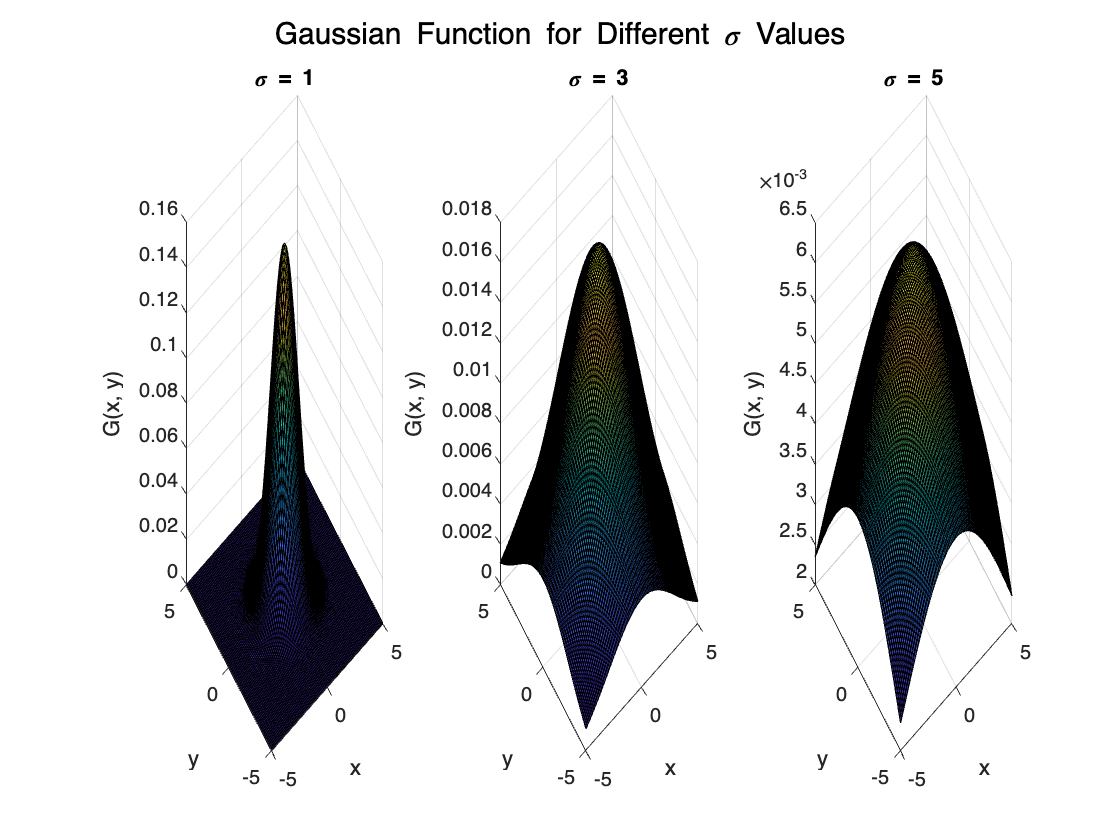


x = linspace(-5, 5, 100);  
y = linspace(-5, 5, 100);
[X, Y] = meshgrid(x, y);

sigma_values = [1, 3, 5];


figure;


for sigma = sigma_values

    G = exp(-(X.^2 + Y.^2) / (2 * sigma^2)) / (2 * pi * sigma^2);

  
    subplot(1, 3, find(sigma_values == sigma));
    surf(X, Y, G);
    title(['\sigma = ', num2str(sigma)]);
    xlabel('x');
    ylabel('y');
    zlabel('G(x, y)');
end


sgtitle('Gaussian Function for Different \sigma Values');

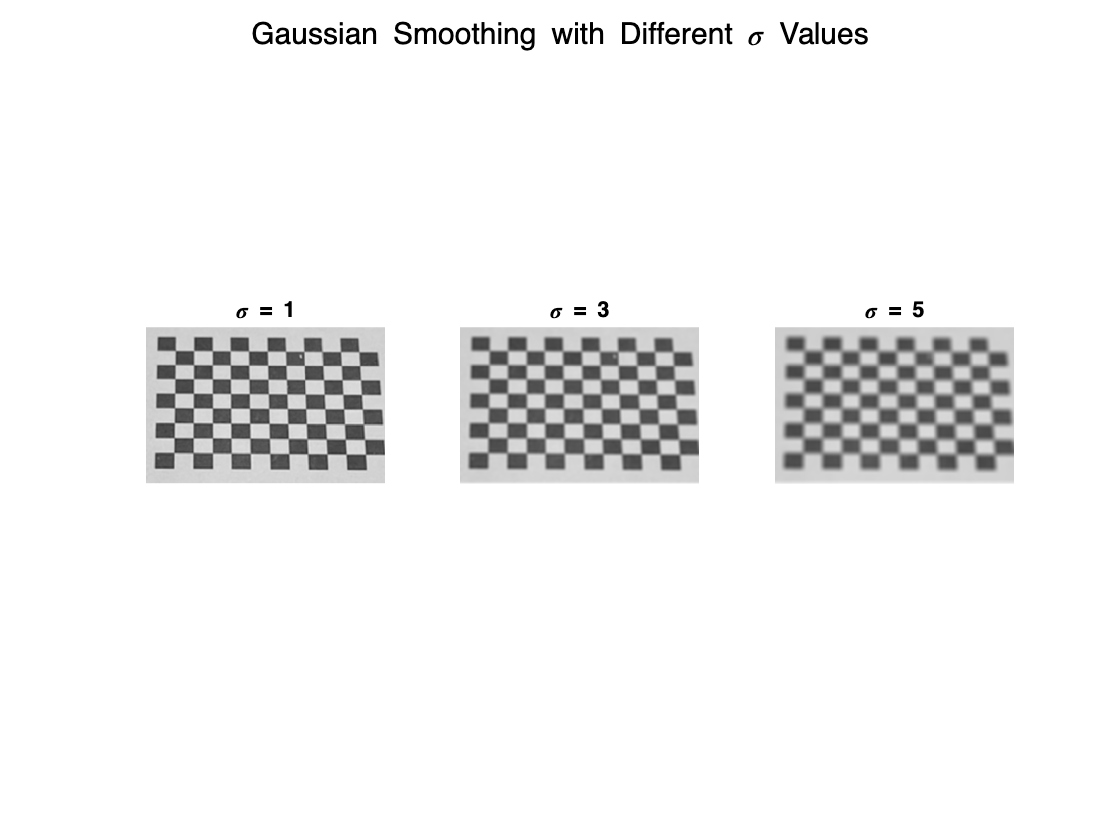


figure(1)

image = imread('Texture.png');

image_gray = rgb2gray(image);



sigma_values = [1, 3, 5];


figure;

for i = 1:length(sigma_values)
    sigma = sigma_values(i);
    
    smoothed_image = imgaussfilt(image_gray,sigma,FilterSize=3*sigma);


    subplot(1, length(sigma_values), i);
    imshow(smoothed_image);
    title(['\sigma = ', num2str(sigma)]);
end


sgtitle('Gaussian Smoothing with Different \sigma Values');

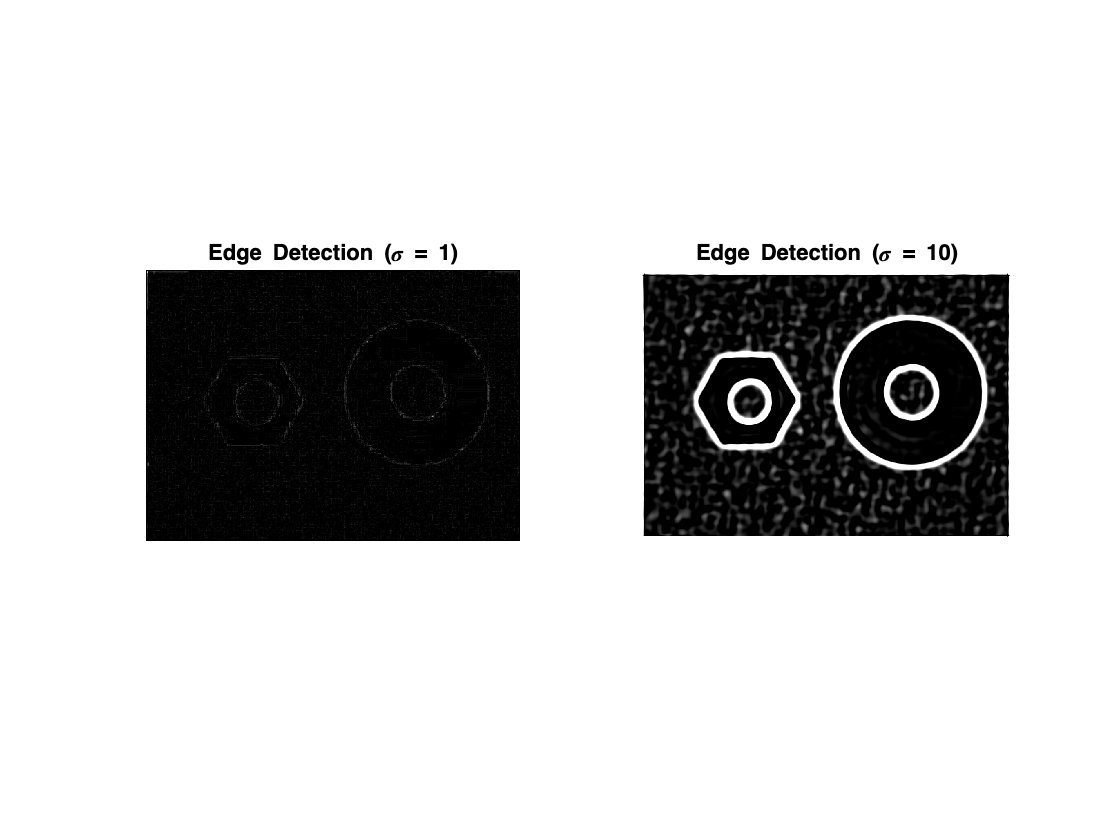


image = imread('nut_and_shell.png');

image_gray = rgb2gray(image);



sigma1 = 1;
sigma2 = 10;


filter_size1 = 3 * sigma1;
filter_size2 = 3 * sigma2;


h1 = fspecial('gaussian', filter_size1, sigma1) - fspecial('gaussian', filter_size1, sigma1 * 1.3);
h2 = fspecial('gaussian', filter_size2, sigma2) - fspecial('gaussian',  filter_size2, sigma2 * 1.3);



edge_image1 = conv2(image_gray,h1,'same');
edge_image2 = conv2(image_gray,h2,'same');

figure;

subplot(1, 2, 1);
imshow(edge_image1);
title(['Edge Detection (\sigma = ', num2str(sigma1), ')']);

subplot(1, 2, 2);
imshow(edge_image2);
title(['Edge Detection (\sigma = ', num2str(sigma2), ')']);


ColorPatternI = [130, 115, 108];
ColorPatternII = [110, 97, 96];

r = zeros(100,200);
g = r;
b = r;
r(:,1:100) = ColorPatternI(1);
g(:,1:100) = ColorPatternI(2);
b(:,1:100) = ColorPatternI(3);
r(:,100:end) = ColorPatternII(1);
g(:,100:end) = ColorPatternII(2);
b(:,100:end) = ColorPatternII(3);
col1 = cat(3,r,g,b);



color_pattern_I = cat(3, 130, 115, 108)/255;
color_pattern_II = cat(3, 110, 97, 96)/255;
combined_image = cat(2, color_pattern_I, color_pattern_II);



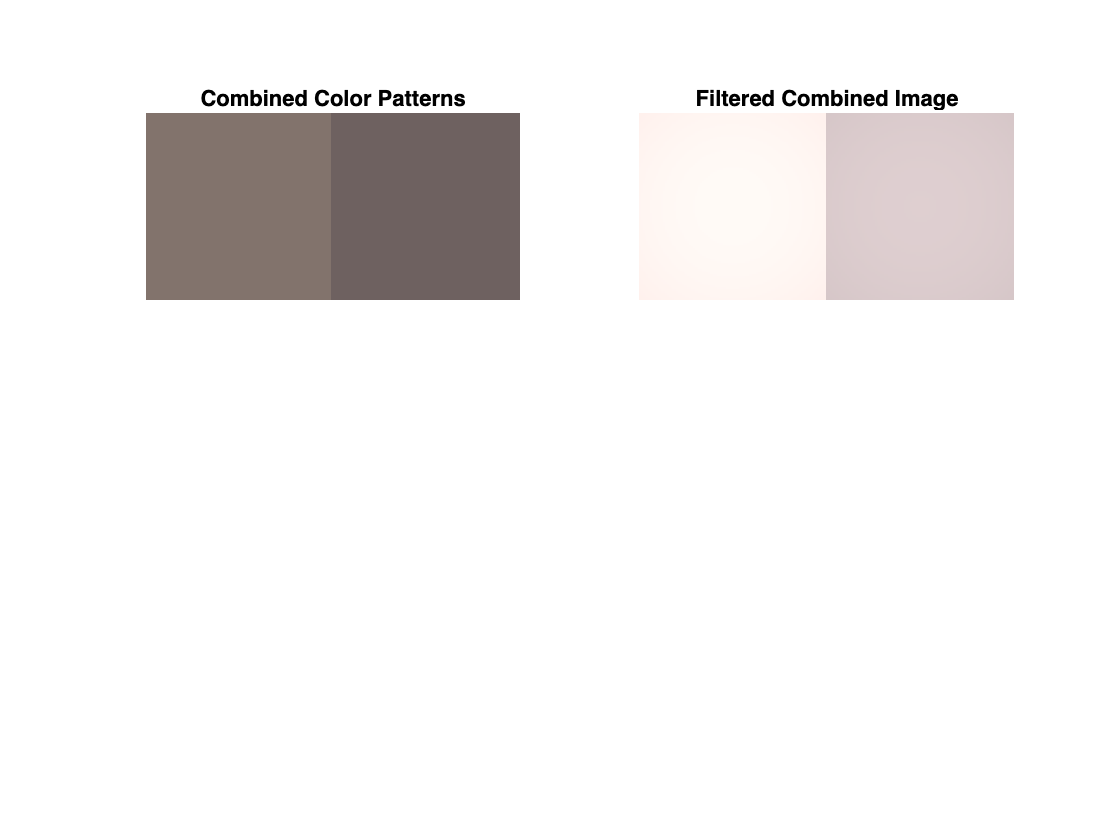


sigma1 = 1;
sigma2 = 10;

[x, y] = meshgrid(-50:50, -50:50);
gaussianKernel1 = exp(-(x.^2 + y.^2)/(2*sigma2^2) / (2 *pi* sigma2^2));


Gs = gaussianKernel1;
DoG = imgaussfilt(combined_image,sigma1) - imgaussfilt(combined_image,sigma2);


R1 = ColorPatternI(1);
G1 = ColorPatternI(2);
B1 = ColorPatternI(3);
h1I = DoG(1) .* R1 + Gs .* (2 * R1 + G1 - B1);
h2I = DoG(2) .* G1 + Gs .* (R1 + 2 * G1 - B1);
h3I = DoG(3) * B1 + Gs * (R1 + G1);
newcol1 = cat(3,h1I,h2I,h3I);



R2 = ColorPatternII(1);
G2 = ColorPatternII(2);
B2 = ColorPatternII(3);
h1II = DoG(1) .* R2 + Gs .* (2 * R2 + G2 - B2);
h2II = DoG(2) .* G2 + Gs .* (R2 + 2 * G2 - B2);
h3II = DoG(3) .* B2 + Gs .* (R2 + G2);
newcol2 = cat(3,h1II,h2II,h3II);

comb2 = cat(2, newcol1,newcol2);


figure;
subplot(2, 2, 1);
imshow(col1/255)
title('Combined Color Patterns');
 
subplot(2, 2, 2);
imshow(uint8(comb2))
title('Filtered Combined Image');


i = 50;
j = 50;
d1 = norm(ColorPatternI-ColorPatternII)

d1 = 29.4618

d = sqrt((newcol1(i,j,1)-newcol2(i,j,1))^2+(newcol1(i,j,2)-newcol2(i,j,2))^2 + (newcol1(i,j,3)-newcol2(i,j,3))^2)

d = 74.2377

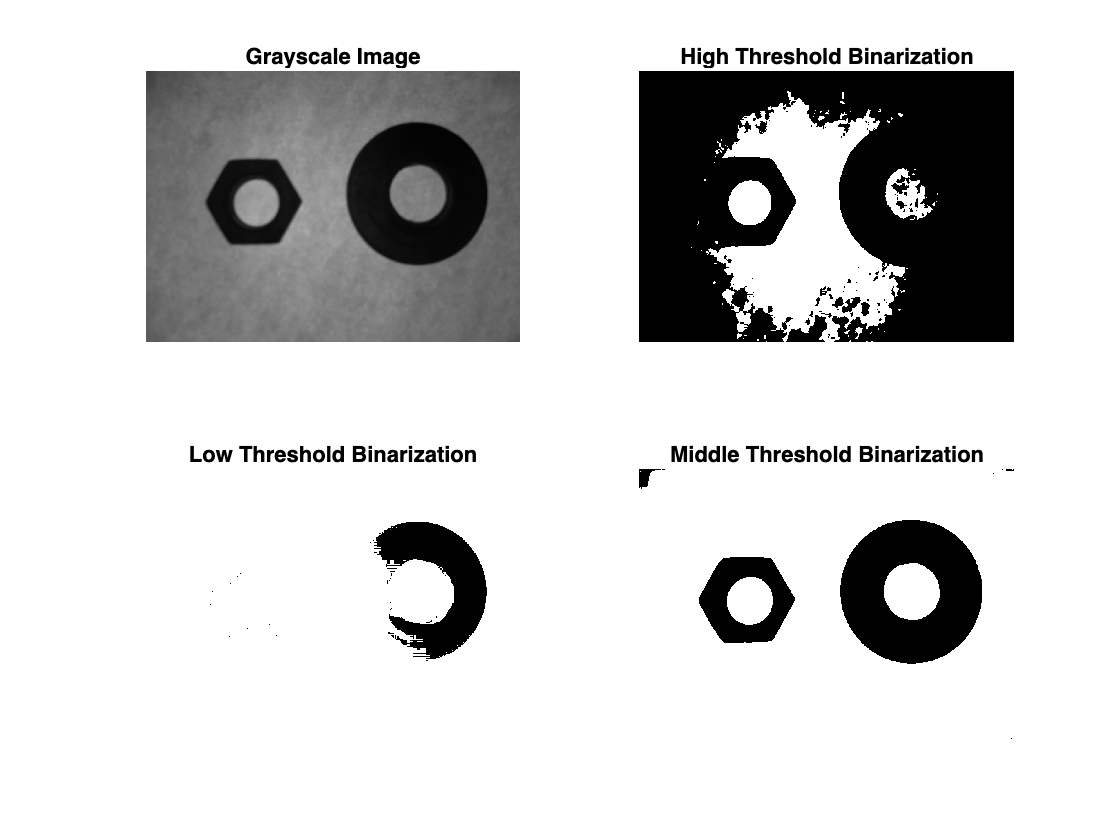


image = imread('nut_and_shell.png');
gray_image = rgb2gray(image);


high_threshold = 125;  
low_threshold = 10;    
middle_threshold = 75;


binary_high = gray_image > high_threshold;
binary_low = gray_image > low_threshold;
binary_middle = gray_image > middle_threshold;


figure;

subplot(2, 2, 1);
imshow(gray_image);
title('Grayscale Image');

subplot(2, 2, 2);
imshow(binary_high);
title('High Threshold Binarization');

subplot(2, 2, 3);
imshow(binary_low);
title('Low Threshold Binarization');

subplot(2, 2, 4);
imshow(binary_middle);
title('Middle Threshold Binarization');




labeled_image = bwlabel(binary_middle);

stats = regionprops(labeled_image, 'Area', 'Centroid');


nut_area = 0;
nut_centroid = [0, 0];
shell_area = 0;
shell_centroid = [0, 0];

for i = 1:numel(stats)
    if stats(i).Area > 10400
        shell_area = stats(i).Area;
        shell_centroid = stats(i).Centroid;
    else
        nut_area = stats(i).Area;
        nut_centroid = stats(i).Centroid;
    end
end


disp(['Nut Area: ', num2str(nut_area)]);

Nut Area: 10331


disp(['Nut Centroid: ', num2str(nut_centroid)]);

Nut Centroid: 272.1537      324.1978


disp(['Shell Area: ', num2str(shell_area)]);

Shell Area: 15072


disp(['Shell Centroid: ', num2str(shell_centroid)]);

Shell Centroid: 668.0594      301.2657


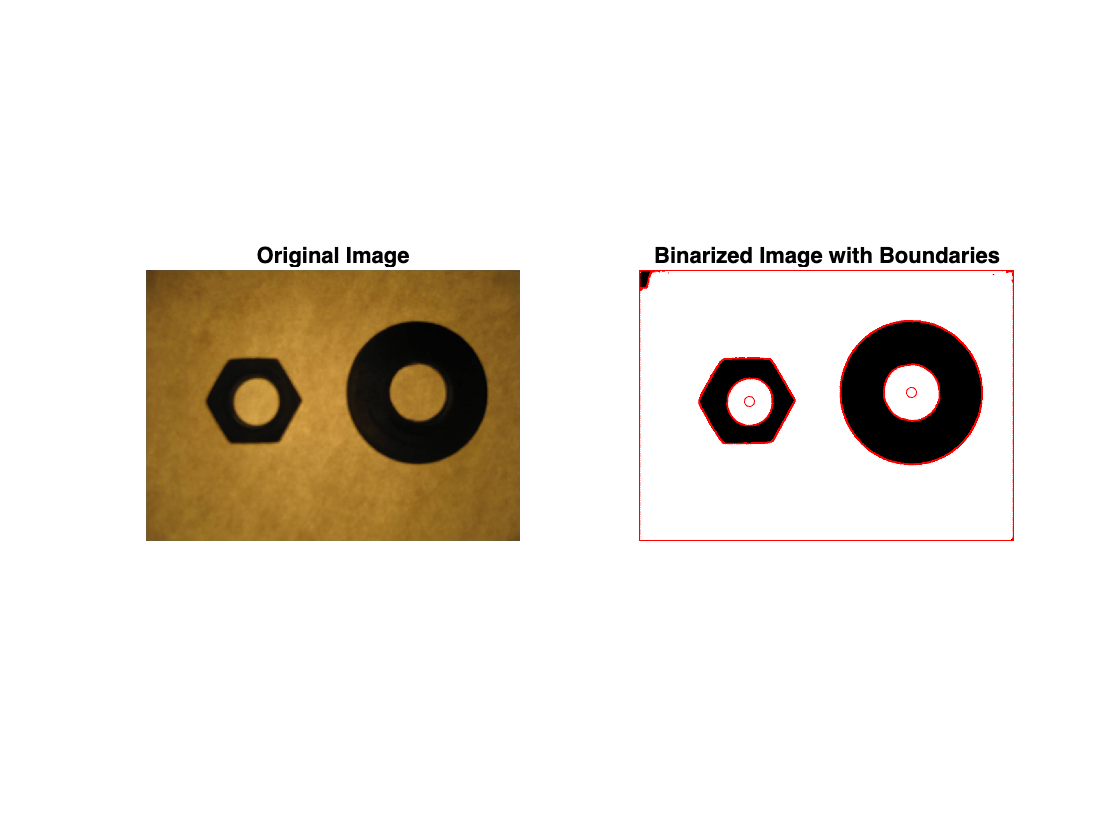

boundaries = bwboundaries(binary_middle);
points = [nut_centroid(1,1) nut_centroid(1,2); shell_centroid(1,1) shell_centroid(1,2)];

figure;
subplot(1, 2, 1);
imshow(image);
title('Original Image');

subplot(1, 2, 2);
imshow(binary_middle);
title('Binarized Image with Boundaries');

hold on;
for k = 1:length(boundaries)
    boundary = boundaries{k};
    plot(boundary(:, 2), boundary(:, 1), 'r', 'LineWidth', 1);
    plot(points(:, 1), points(:, 2), 'ro', 'MarkerSize', 5);
end
hold off;